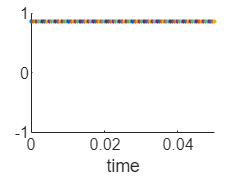


clear all;
close all;
colors = npg(100);
F=5/2;
sigmax = spinOp(F,'x');
sigmay = spinOp(F,'y');
sigmaz = spinOp(F,'z');


%% 输入变量
start_point = 0;   % 不分析前几个周期
N = 10;   % 共计N个周期
dN = 0.05;   % 计算步长为dN个周期

initial_angle = pi/16;   % 初始偏离理想极化

angle = 3/400;   % 横向磁场角度
tensor = 0.46524*1.5*5*0;   % tensor shift大小
Bz = 20;   % Frequency量纲

phase0 = 0.5*pi;  % 第一次过零点前经历的相位


ham0 = 1*sigmax+1*sigmax^2;
%ham1 = 2*pi*( (angle*sigmay+sigmaz)*Bz/sqrt(1+angle^2) + tensor*sigmaz^2);   % omega量纲


freq_center = Bz*F/0.5;   % Frequency量纲

initial_0 = zeros(2*F+1,1);
initial_0(1) = 1;
initial_0 = ham_evolve(sigmax+sigmax^2,initial_0,initial_angle);   % 171-ROT对173极化态的影响
initial = ham_evolve(ham1,initial_0,0.75*78/108/freq_center);   % 171-ROT和173-ROT之间的等待时间
initial = ham_evolve(ham0,initial,0);


timestep = dN*1/freq_center;
timeend = N*1/freq_center;
timelist = [0:timestep:timeend];


for k = 1:length(timelist)
    precess_state = ham_evolve(ham1,initial,timelist(k));
    final_state(:,k) = ham_evolve(ham0,precess_state,pi/2);
end
%pop_state = abs(precess_state).^2;
pop_state = abs(final_state).^2;

sz(:) = (pop_state(1,:)-pop_state(2*F+1,:))./(pop_state(1,:)+pop_state(2*F+1,:));
f1 = figure;
scatter(timelist,sz,'.');
ylim([-1 1]);
xlim([0/freq_center 5/freq_center]);
xlabel('time');

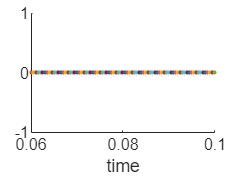


f2 = figure;
scatter(timelist,sz,'.');
ylim([-1 1]);
xlim([timeend-4/freq_center timeend]);
xlabel('time');

%set(gcf,'visible','on');



% [contrast,cycle_n,zero_list,zero_mark] = cycle_count_function(sz,timelist,phase0);
% 
% for k = 1:length(zero_list)
%     zero_state1 = ham_evolve(ham1,initial,zero_list(k));
%     zero_state(:,k) = ham_evolve(ham0,zero_state1,pi/2);
% end
% 
% pop_state1 = abs(zero_state).^2;
% zero_sz(:) = (pop_state1(1,:)-pop_state1(2*F+1,:))./(pop_state1(1,:)+pop_state1(2*F+1,:));
% zero_residual_phase = zero_sz/contrast.*zero_mark;
% 
% zero_phase = phase0+2*pi*[0:0.5:cycle_n]+zero_residual_phase;
% freq_list = zero_phase./zero_list/(2*pi);
% cycle_list = [phase0/(2*pi):0.5:phase0/(2*pi)+cycle_n];
% 
% freq_list(1:start_point*2) = [];
% cycle_list(1:start_point*2) = [];
% 
% f_mean = mean(freq_list);
% f_std = std(freq_list);
% 
% figure;
% plot(cycle_list,freq_list,'.','Color',colors(5,:),'MarkerSize',12);
% xlim([min(cycle_list),max(cycle_list)]);
% y_min = min(freq_list);
% y_max = max(freq_list);
% y_diff = y_max-y_min;
% ylim([y_min-y_diff*0.5,y_max+y_diff*0.5]);
% title('Freq','FontSize',20,'FontName','arial','FontWeight','bold');
% xlabel('cycle');
% legend(['freq = ',num2str(f_mean,'%.8f'),'Hz',...
%     newline 'error = ',num2str(f_std,'%e'),'Hz']);
% set(gca,'FontSize',15,'FontName','arial','FontWeight','bold');
% set(gca,'YGrid','on');
% set(gcf,'Visible','on');


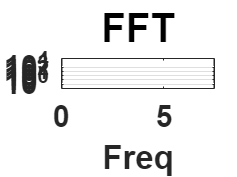


%% FFT

f3 = figure;
freq = fft(sz);   % Frequency量纲
plot(1./timestep/length(timelist)*(0:(length(timelist)-1)),abs(freq),'LineWidth',2,"Color",'[0.75 0.07 0.17]')
set(gca,'FontSize',15,'FontName','arial','FontWeight','bold','YScale','log');
xlim([0 7.5]);
%xlim([0 30]);
ylim([10^-1 10^6])
xlabel('Freq');
title('FFT','FontSize',20,'FontName','arial','FontWeight','bold');
%set(gcf,'visible','on');
set(gca,'YGrid','on','YTick',[1 10 100 1000 10000],'YMinorGrid','off');

function final = ham_evolve(ham,initial,time)
try
    final = expm(-1i*ham.*time)*initial;
catch 
    disp("Wrong Solution!!");
end
end